# Data analysis of localization confidence

- Does confidence reflect performance? Check correlation between error and confidence

- Is confidence modulated by cue discrepancy and cue reliability? Plot perceptual and causal confidence as a function of discrepancy (congruent, a bit incongruent, very incongruent trials); lines: low and high visual reliability

- Do people report lower confidence for incongruent trials despite identical perceptual and causal decisions? Compare confidence of perceptual and causal metamers

clear; clc; close all;
sub_slc     = 1;
ses_slc     = 1:2;

% manage path
cur_dir      = pwd;
[project_dir, ~]= fileparts(fileparts(cur_dir));
out_dir      = fullfile(cur_dir, 's1Fig');
addpath(genpath(fullfile(project_dir,'func')))
data_dir     = fullfile(project_dir, 'data','biLoc');
if ~exist(out_dir,'dir') mkdir(out_dir); end

% organize data
[org_resp, org_conf, org_err, ExpInfo, ~, ScreenInfo] = org_data(sub_slc,ses_slc,'biLoc');

% organize by discrepancy
aud_locs = ExpInfo.speakerLocVA(ExpInfo.audIdx);
conf_by_diff = org_by_diffs(org_conf, aud_locs); % {diff} cue x reliability x rep 

% conditions
seq         = ExpInfo.randAVIdx;
audIdx      = ExpInfo.audIdx;
visIdx      = ExpInfo.visIdx;
cueIdx      = ExpInfo.cueIdx;
visReliIdx  = ExpInfo.visReliIdx;
num_rep     = ExpInfo.nRep;
deg_per_px  = rad2deg(atan(170 / 2 / ExpInfo.sittingDistance)) .* 2 / ScreenInfo.xaxis;
cue_label   = {'Post-cue: A','Post-cue: V'};
rel_label   = {'High visual reliability','Low visual reliability'};
vis_locs    = [ExpInfo.targetPixel] .* deg_per_px;
diffs       = zeros(length(aud_locs), length(vis_locs));
for i = 1:length(aud_locs)
    for j = 1:length(vis_locs)
        diffs(i, j) = aud_locs(i) - aud_locs(j);
    end
end
diff_locs   = unique(abs(diffs))';

## Plot set up

lw = 2;
fontSZ = 15;
titleSZ = 20;
dotSZ = 80;
clt = [30, 120, 180; % blue
    227, 27, 27;  % dark red
    repmat(125, 1, 3)]./255;
%     251, 154, 153]./255; % light red


## Sanity check: localization response

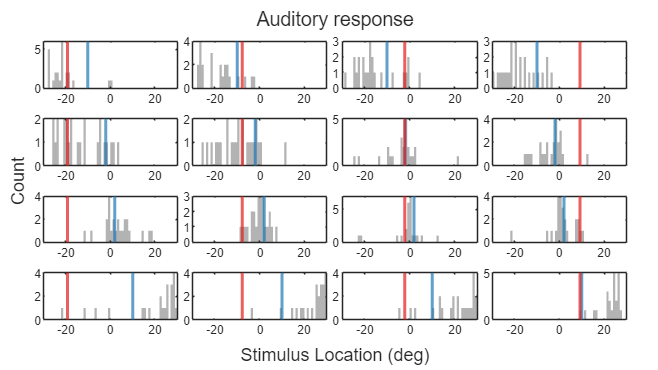

figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Auditory response')
xlabel(t, 'Stimulus Location (deg)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
         curr_resp = squeeze(org_resp(a, v, 1, :, :));
         nexttile
         h = histogram(curr_resp, numel(curr_resp),'BinWidth',1);
         h.FaceColor = repmat(0.5, 1, 3); 
         h.EdgeColor = 'none';

         xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
         xline(vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

         xlim([-30, 30])
    end
end

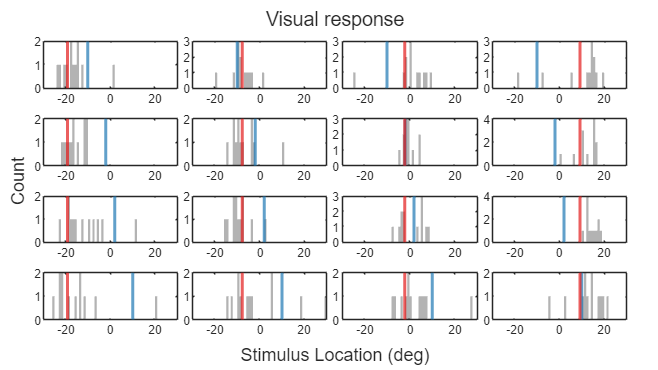



figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Visual response')
xlabel(t, 'Stimulus Location (deg)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
         curr_resp = squeeze(org_resp(a, v, 2, 2, :));
         nexttile
         h = histogram(curr_resp, numel(curr_resp),'BinWidth',1);
         h.FaceColor = repmat(0.5, 1, 3); 
         h.EdgeColor = 'none';

         xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
         xline(vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

         xlim([-30, 30])
    end
end

## Sanity check: bias in congruent trials

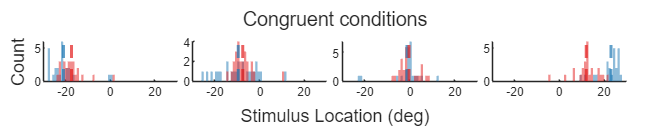

figure
set(gcf, 'Position',[0 0 1000 200])
hold on
t = tiledlayout(1, 4);
title(t, 'Congruent conditions')
xlabel(t, 'Stimulus Location (deg)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for ii = 1:numel(audIdx)

    nexttile;
    hold on

    for rr = 1:numel(cueIdx)

        curr_resp = squeeze(org_resp(ii, ii, rr, :, :));
        h = histogram(curr_resp, numel(curr_resp),'FaceAlpha',0.5,'BinWidth',1);
        h.FaceColor = clt(rr,:);
        h.EdgeColor = 'none';

        mean_congruent(ii, rr) = mean(curr_resp,'all');
        std_congruent(ii, rr)  = std(curr_resp,[],'all');
        xline(mean_congruent(ii, rr),'--','LineWidth',lw,'Color',clt(rr,:))

        xlim([-30,30])
   end

end

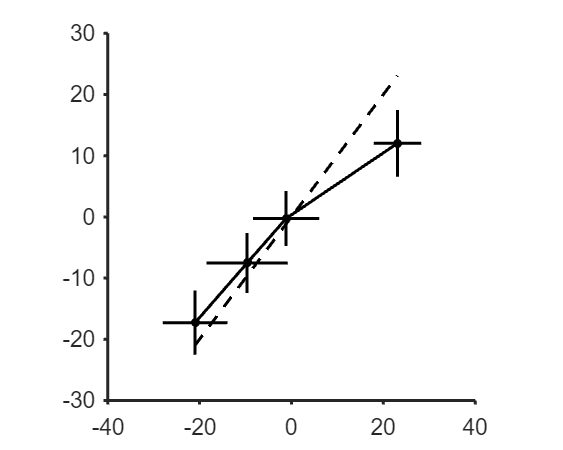



figure
set(gcf, 'Position', [0,0,500,400]); hold on
set(gca, 'LineWidth', lw, 'FontSize', fontSZ, 'TickDir', 'out')
axis equal; axis square

scatter(mean_congruent(:,1),mean_congruent(:,2),'filled','k')
e1 = errorbar(mean_congruent(:,1), mean_congruent(:,2), std_congruent(:,2),'k','LineWidth',lw);
e2 = errorbar(mean_congruent(:,1), mean_congruent(:,2), std_congruent(:,1), 'k','horizontal','LineWidth',lw);
e1.CapSize = 0;
e2.CapSize = 0;
plot(max(mean_congruent,[],"all"))
maxV = max(mean_congruent(:));
minV = min(mean_congruent(:));
plot([minV, maxV],[minV, maxV],'k--','LineWidth',lw)

## What's the relationship between relative error and confidence

% % Assuming 'errors' and 'confidences' are your data variables
% err = org_err(:); % Your error data here
% conf = org_conf(:);% Your confidence data here
% 
% % Number of bins
% num_bins = 10;
% 
% % Bin the error data
% [~,~,bin_indices] = histcounts(err, num_bins);
% 
% % Calculate the proportion of high confidence for each bin
% bin_proportions = accumarray(bin_indices, conf, [num_bins, 1], @mean, NaN);
% 
% % Count the number of trials in each bin
% trials_per_bin = accumarray(bin_indices, 1, [num_bins, 1], @sum, 0);
% 
% % Calculate bin midpoints for plotting
% bin_edges = linspace(min(err), max(err), num_bins+1)';
% bin_midpoints = (bin_edges(1:end-1) + bin_edges(2:end)) / 2;
% 
% % Plot actual proportions
% figure;
% set(gcf, 'Position', [0,0,500,400]); hold on
% set(gca, 'LineWidth', lw, 'FontSize', fontSZ, 'TickDir', 'out')
% % plot(bin_midpoints, bin_proportions, 'ko-', 'LineWidth', 2);
% scatter(bin_midpoints, bin_proportions, trials_per_bin*5, 'black','filled'); % Adjust 10 as needed to scale dot sizes appropriately

## Visualize logistic regression between error and confidence

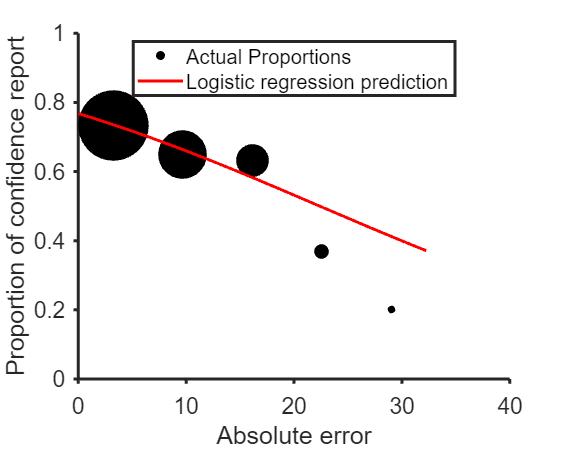

% Assuming 'errors' and 'confidences' are your data variables
err = abs(org_err(:)); % Your error data here
conf = org_conf(:);% Your confidence data here

% Number of bins
num_bins = 5;

% Bin the error data
[~,~,bin_indices] = histcounts(err, num_bins);

% Calculate the proportion of high confidence for each bin
bin_proportions = accumarray(bin_indices, conf, [num_bins, 1], @mean, NaN);

% Count the number of trials in each bin
trials_per_bin = accumarray(bin_indices, 1, [num_bins, 1], @sum, 0);

% Calculate bin midpoints for plotting
bin_edges = linspace(min(err), max(err), num_bins+1);
bin_midpoints = (bin_edges(1:end-1) + bin_edges(2:end)) / 2;

% Fit a logistic regression model
mdl = fitglm(err, conf, 'Distribution', 'binomial');

% Generating a range of values for prediction
org_err_range = linspace(min(err), max(err), 1000)';
% Predicting probabilities using the logistic regression model
predicted_conf = predict(mdl, org_err_range);

% Plot actual proportions
figure;
set(gcf, 'Position', [0,0,500,400]); hold on
set(gca, 'LineWidth', lw, 'FontSize', fontSZ, 'TickDir', 'out')
% plot(bin_midpoints, bin_proportions, 'ko-', 'LineWidth', 2);
scatter(bin_midpoints, bin_proportions, trials_per_bin*5, 'black','filled'); % Adjust 10 as needed to scale dot sizes appropriately
hold on;

% Plotting the model prediction
plot(org_err_range, predicted_conf, 'r-', 'LineWidth', 2);

% Enhance the plot
ylim([0,1])
xlabel('Absolute error');
ylabel('Proportion of confidence report');
legend('Actual Proportions', 'Logistic regression prediction', 'Location', 'Best');

## Is confidence modulated by cue discrepancy and cue reliability?

[ ] add bootstrapped errorbars

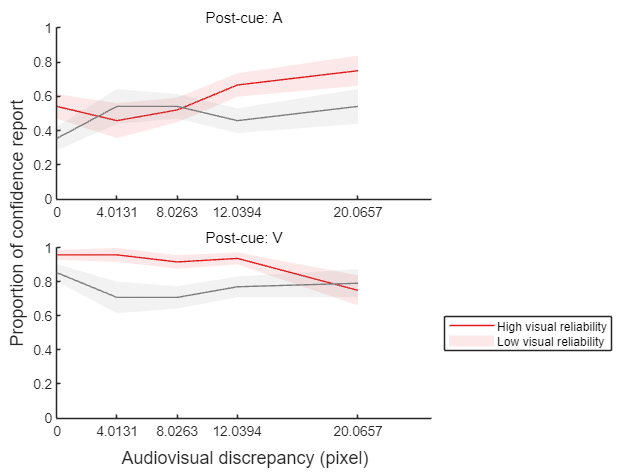

figure; hold on 

t = tiledlayout(2, 1);
xlabel(t, 'Audiovisual discrepancy (deg)');
ylabel(t, 'Proportion of confidence report');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for cue = 1:numel(cueIdx)
    nexttile
    title(cue_label{cue})
    hold on
    for rel = 1:numel(visReliIdx)
        [p_conf, se_conf] = deal(NaN(1, numel(diff_locs)));
        for diff = 1:numel(diff_locs)
            i_conf = squeeze(conf_by_diff{diff}(cue, rel, :))';
            p = sum(i_conf)/numel(i_conf);
            p_conf(diff) = p;
            se_conf(diff) = sqrt((p*(1-p))/numel(i_conf));
        end
        plot(diff_locs, p_conf, 'Color',clt(rel+1,:))
        patch([diff_locs, fliplr(diff_locs)], ...
            [p_conf - se_conf, fliplr(p_conf + se_conf)], ...
            clt(rel+1,:),'EdgeColor','none','FaceAlpha',0.1)

        ylim([0, 1])
    end
    xticks(diff_locs)
end
legend(rel_label, 'Location', 'eastoutside');

## Compare metamer trials

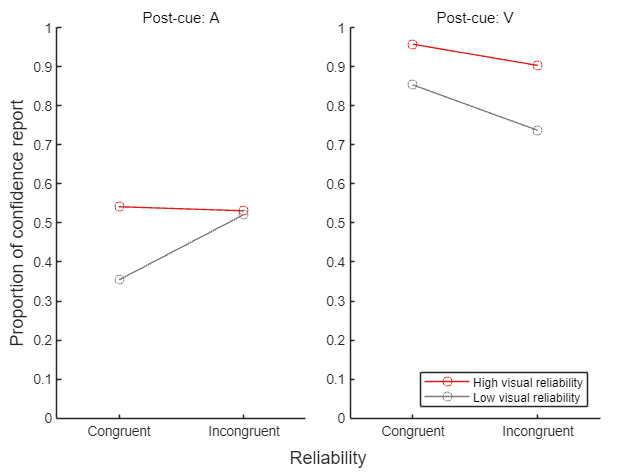

figure; hold on

t = tiledlayout(1, 2);
xlabel(t, 'Reliability');
ylabel(t, 'Proportion of confidence report');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for cue = 1:2

    nexttile; hold on
    title(cue_label{cue})

    all_con = cell(2);
    all_incon = cell(2);

    for rel = 1:2

        % for 4 locations of congruent conditions
        for i  = 1:4

            slc_resp = squeeze(org_resp(:,:,cue,rel,:));
            con_conf = squeeze(org_conf(i,i,cue, rel,:));
            all_con{cue, rel} = [all_con{cue, rel}; con_conf];

            con_resp = slc_resp(i,i,:);
            i_mu = mean(con_resp);
            i_sd = std(con_resp,[],'all');

            lb = i_mu - 0.5*i_sd;
            ub = i_mu + 0.5*i_sd;

            withinRange = (slc_resp>= lb) & (slc_resp<= ub);
            linearIndices = find(withinRange);

            [I1, I2, I3] = ind2sub(size(slc_resp), linearIndices);

            incon_conf = [];

            for j = 1:length(linearIndices)

                if I1(j) == i && I2(j) == i
                else
                    incon_conf = [incon_conf; org_conf(I1(j), I2(j), cue, rel, I3(j))];
                end

            end

            all_incon{cue, rel} = [all_incon{cue, rel}; incon_conf];

        end

        p_con = sum(all_con{cue, rel},'all')/numel(all_con{cue, rel});
        p_incon = sum(all_incon{cue, rel},'all')/numel(all_incon{cue, rel});

        plot([1,2], [p_con, p_incon],'o-','Color',clt(rel+1,:))
        xlim([0.5, 2.5])
        xticks([1,2])
        xticklabels({'Congruent','Incongruent'})
        ylim([0, 1])

    end

    if cue == 2

        legend(rel_label, 'Location', 'southeast');

    end
   
end